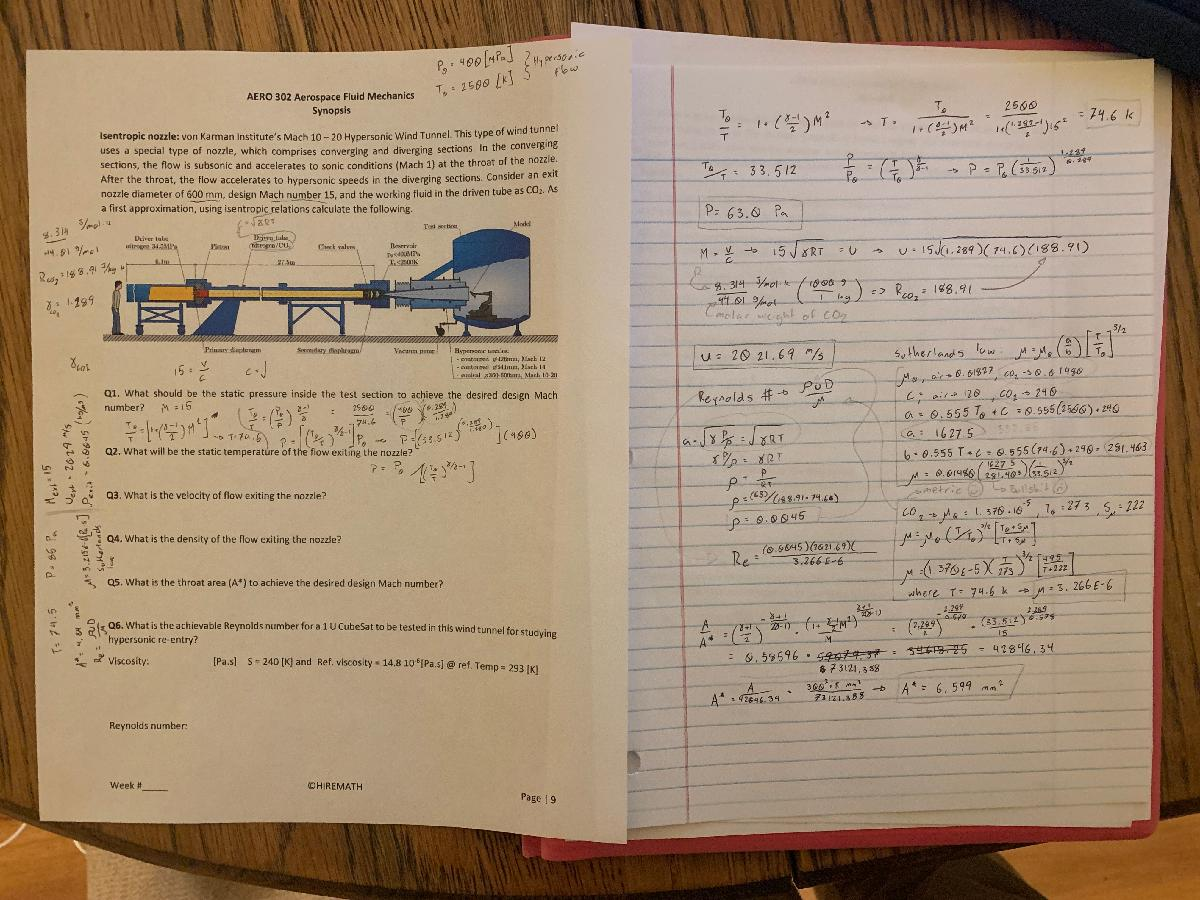

clc;clear variables;
format long g
To = 2500;%[K]
Po = 400;%[mpa]
Po = Po*10^6;%[mpa > pa]
mach = 15;
gamma = 1.289;
Ta = To;%[K]

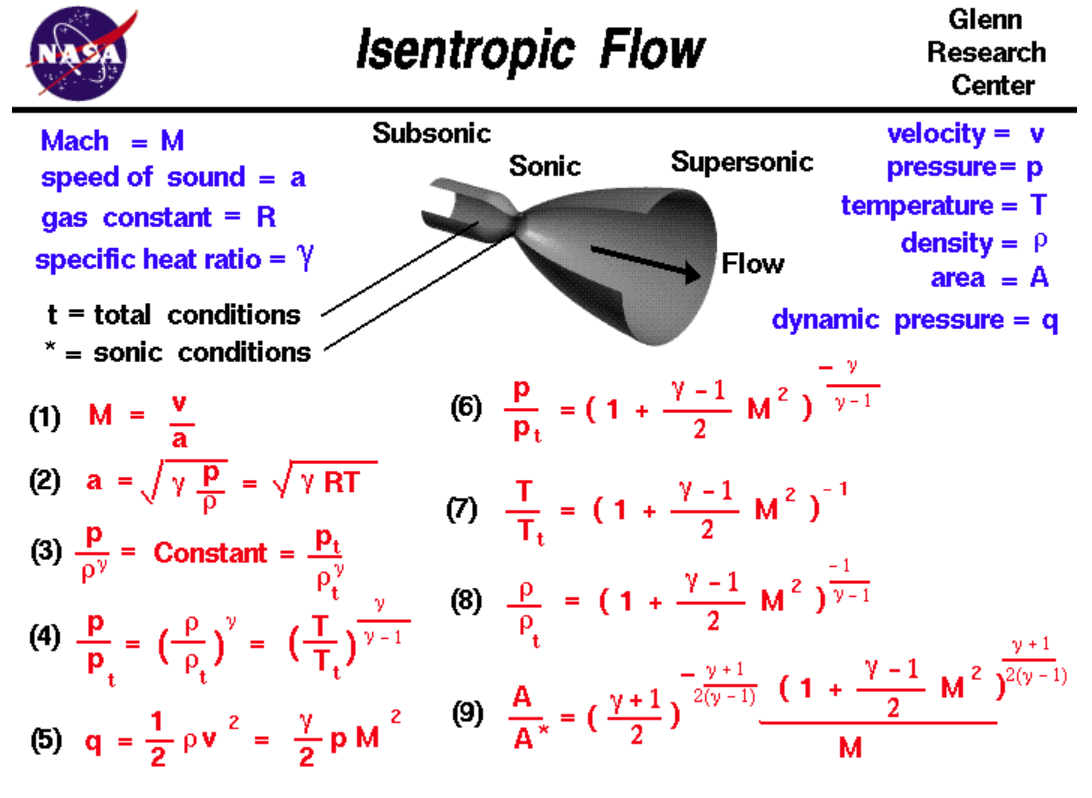

Q1, what should be the static pressure inside the test section to achive the mach number

R = 8.314/(44.011/1000);%[J/kg/K]
[a,Pratio,Tratio,Ts,RHOratio,Aratio] = IsentropicFlow(gamma,mach,Ta,R);
Pstatic = Pratio*Po;%pratio * ptotal [Pa] correct

Q2, static temp

Tstatic = Tratio*To; %correct

Q3,velocity of flow exiting nozzle

Ve = mach*a; 
disp(Ve)

          2021.66270943465



Q4, what is density at exit

rhoS = Pstatic/((a^2)*(1/gamma));
disp(rhoS)

        0.0044703232243345



Q5, what is throat area

A = (1/Aratio)*(pi*300^2);%[mm]
disp(A)

          6.59900838049167

